MECHENG 736/730 - Assignment 1: Measuring and decoding the electroencephalogram (EEG)

Student: Gabriel Werpel Fernandes - gfer533@aucklanduni.ac.nz - UoA ID: 989055637

**Task 1:**

% Load Data
[originalData, originalFs] = audioread('byb_gabe.wav');

% Remove data points above 180s
originalData(end - 8298:end) = [];

% Initialize arrays to store alpha and beta power values
alphaValues = [];
betaValues = [];
labels = []; % 0 for closed, 1 for open

% Resample data from 10,000 Hz to 500 Hz
newFs = 500;
[p, q] = rat(newFs/originalFs);
resampledData = resample(originalData, p, q);

% Separate segments by 36: each segment corresponds to a specific time
% window of the EEG recording. The data is then divided into "open" and "closed" segments.
numSegments = 36;
segmentSize = length(resampledData)/numSegments;
closedAll = [];
openAll = [];
for i = 1:2:numSegments
    closedVarName = ['closed', num2str((i+1)/2)]
    openVarName = ['open', num2str((i+1)/2)]

    startIdx = (i-1)*segmentSize + 1;
    endIdx = startIdx + segmentSize -1;
    closedSegment = resampledData(startIdx:endIdx);
    closedAll = [closedAll; closedSegment];
    assignin('base', closedVarName, resampledData(startIdx:endIdx))

    startIdx = endIdx + 1;
    endIdx = startIdx + segmentSize - 1;
    openSegment = resampledData(startIdx:endIdx);
    openAll = [openAll; openSegment];
    assignin('base', openVarName, resampledData(startIdx:endIdx))
end

closedVarName = 'closed1'

openVarName = 'open1'

closedVarName = 'closed2'

openVarName = 'open2'

closedVarName = 'closed3'

openVarName = 'open3'

closedVarName = 'closed4'

openVarName = 'open4'

closedVarName = 'closed5'

openVarName = 'open5'

closedVarName = 'closed6'

openVarName = 'open6'

closedVarName = 'closed7'

openVarName = 'open7'

closedVarName = 'closed8'

openVarName = 'open8'

closedVarName = 'closed9'

openVarName = 'open9'

closedVarName = 'closed10'

openVarName = 'open10'

closedVarName = 'closed11'

openVarName = 'open11'

closedVarName = 'closed12'

openVarName = 'open12'

closedVarName = 'closed13'

openVarName = 'open13'

closedVarName = 'closed14'

openVarName = 'open14'

closedVarName = 'closed15'

openVarName = 'open15'

closedVarName = 'closed16'

openVarName = 'open16'

closedVarName = 'closed17'

openVarName = 'open17'

closedVarName = 'closed18'

openVarName = 'open18'

% Nyquist Filtering: a bandpass Butterworth filter is applied to the data to retain frequencies between 1 Hz and 100 Hz.
F_Nyquist_Hz = newFs/2;
F_CUT1_HZ = 1;
F_CUT2_HZ = 100;
[b,a] = butter(2,[F_CUT1_HZ/F_Nyquist_Hz, F_CUT2_HZ/F_Nyquist_Hz]);
EEG_Eyes_Closed_filt = filter(b,a,closedAll);
EEG_Eyes_Open_filt = filter(b,a,openAll);

% Get P0: computing Max Power
P0 = sum([EEG_Eyes_Closed_filt EEG_Eyes_Open_filt].^2) / length([EEG_Eyes_Closed_filt EEG_Eyes_Open_filt]);

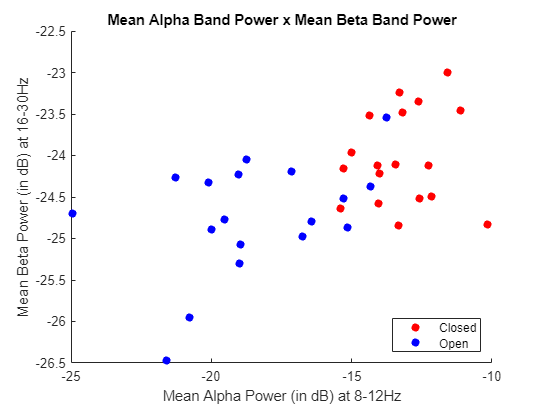

% Plotting: the function computes the power spectrum and extracts the alpha and beta power. 
figure;
hold on;
numPairs = numSegments/2;
for i = 1:numPairs
    closedVarName = ['closed', num2str(i)];
    openVarName = ['open', num2str(i)];

    closedSegment = evalin('base', closedVarName);
    openSegment = evalin('base', openVarName);

    [alphaPowerClosed, betaPowerClosed] = computePower(closedSegment, P0);
    [alphaPowerOpen, betaPowerOpen] = computePower(openSegment, P0);

    % Append the computed values to the arrays
    alphaValues = [alphaValues; alphaPowerClosed; alphaPowerOpen];
    betaValues = [betaValues; betaPowerClosed; betaPowerOpen];
    labels = [labels; 0; 1]; % 0 for closed, 1 for open

    scatter(alphaPowerClosed, betaPowerClosed, 'r', 'filled'); % Red for closed
    scatter(alphaPowerOpen, betaPowerOpen, 'b', 'filled'); % Blue for open
end
legend('Closed', 'Open', 'Location', 'southeast');
xlabel('Mean Alpha Power (in dB) at 8-12Hz');
ylabel('Mean Beta Power (in dB) at 16-30Hz');
title('Mean Alpha Band Power x Mean Beta Band Power');
hold off;

% Combine the arrays and labels into a single matrix
combinedData = [alphaValues, betaValues, labels];

% Save the combined data to a .mat file
save('combinedEEGData.mat', 'combinedData');

% Function: computePower
% Description: This helper function computes the power spectrum of a given EEG segment and extracts the alpha and beta power.
% Inputs:
% - sig: The EEG segment.
% - P0: The power of the EEG signal.

function [alphaPower, betaPower] = computePower(sig, P0)
    sigDuration = 5; %seconds

    % Fourier Transform
    Fsig = fft(sig) / length(sig);
    aFsig = abs(Fsig);
    aFsig = 2*aFsig(1:floor(length(Fsig)/2));
    aFsig(1) = aFsig(1)/2;
    f_axis_Hz = 1/sigDuration * (0:(length(aFsig)-1));

    % Power Spectrum
    p_spectrum = aFsig.^2;
    p_spectrum = 2*p_spectrum(1:floor(length(Fsig)/2));
    p_spectrum(1) = p_spectrum(1)/2;
    p_spectrum_dB = 10*log10(p_spectrum/max(P0));

    % Extracting Alpha and Beta Power
    mask1 = (f_axis_Hz > 8 & f_axis_Hz <= 12);
    alphaPower = mean(p_spectrum_dB(mask1));
    mask2 = (f_axis_Hz > 16 & f_axis_Hz <= 30);
    betaPower = mean(p_spectrum_dB(mask2));
end